# **AuthorsRANSAC**

*The work can be done in groups of up to 3 students. Please complete the following fields with your group number and list your names along with HDU ID numbers.*

`[HDU-AT3-24] Computer Vision`

 1. Zhu Chenhao, 22320630

 2. Liu Ange, 22320627

 3. Yang Lanqin, 22320622

5

The task and guidelines were prepared by Andrei Zhdanov and Sergei Shavetov, ITMO University, 2025.

# **Practical Assignment No 4. Face Detection using Viola-Jones Approach**

Study of Viola-Jones approach for detection of faces and part of bodies in the images.

***Note.**** Please note that when doing the practical assignment you are not allowed to use the “Lenna” image or any other image that was used either in this book or during the presentation*

## Introduction

The Viola-Jones face detector method is based on the following concepts: 

- Haar-like feaures as weak classifiers. 

- Integral image representation for fast calculation of Haar-like features. 

- AdaBoost training method to combine weak classifiers into a strong classifier. 

- Combining of strong classifiers into a cascade classifier.

### Haar-like features 

Haar-like feature is a kind of a weak classifier. It can be defined as the difference of the sum of pixels of areas inside the rectangle, which can be at any position and scale within the original image. In a traditional Viola-Jones face detector algorithm 4 types of Haar-like features that are shown in the picture are used:

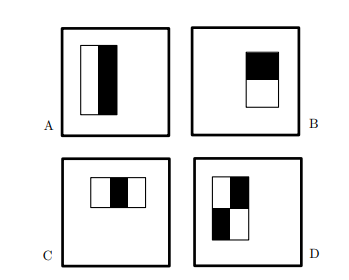

To calculate the value of the Haar-like feature we need to calculate sums of pixels inside rectangular areas of the image and do it as fast as possible.


$$value = \sum{(pixels\ in\ black\ area)} - \sum{(pixels\ in\ white\ area)}.$$


Obviously, the straightforward calculation of the sum of pixel values in a rectangle would require number of sums that is equal to number of pixels minus one. To speed up the feature calculation, an integral image representation is used. In this representation each pixel stores the sum of all pixel values that are positioned to the left and above of the current pixel. To calculate the sum of pixel intensity values in an arbitrary rectangle we need to access four pixels of an integral image which are located at the corners of the rectangle:

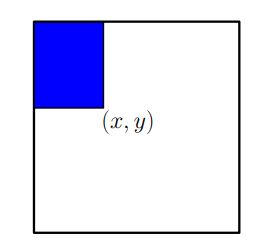


$$𝑠𝑢𝑚 = 𝐷 - 𝐵 - 𝐶 + 𝐴, $$


where 𝐷 is the bottom right corner of the rectangle, 𝐵 is a pixel one pixel above the top right corner of the rectangle, 𝐶 is the pixel to one pixel the left of the bottom left corner of the rectangle, and 𝐴 is a pixel one pixel above and to the left of the top left corner of the rectangle.

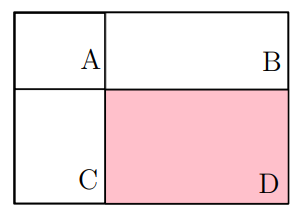

The set of Haar-like features (which are weak classifiers) can be combined with a weighted sum of their values to form a more complex strong classifier. The training algorithm is called AdaBoost. It consists of several boosting rounds, and each boosting round is a selection of a best weak Haar-like feature to classify the training set with taking the classification errors of the previous rounds into an account.

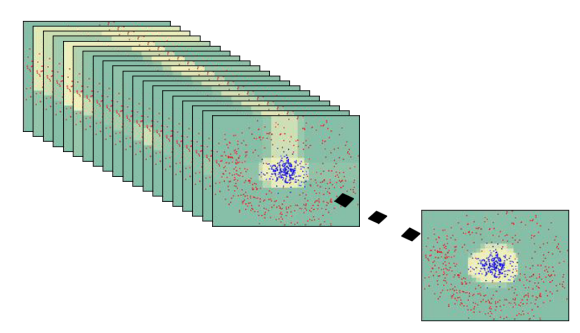

Formally, the AdaBoost training scheme algorithm can be described with following steps:

    1. On an input we have a training set $T = \{(x_i, y_i) | x_i \in X, y_i \in \{-1,1\}\}$ and a set of all possible weak classifiers {ℎ}.

    2. Initialize the weights for a training set items to be equal and sum up to 1. $D_1(i) = 1 / m$, where 𝑚 is a number of training set items.

    3. Do 𝐾 iterations:

        (a) Choose $h_k$ from a set of weak classifiers 𝐻, so that the weighted classification error probability is minimal (the probability of the wrong classification with taking weights into an account):


$$\epsilon_k = Pr_{i~D_k}[h_k (x_i) \neq y_i]$$


        (b) Calculate the weight of the currently selected weak classifier basing on its classification error probability: 


$$\alpha_k = \frac{1}{2} \ln \left({\frac{1 - \epsilon_k}{\epsilon_k}}\right).$$


        (c) Reweigh the training set with new weights:


$$D_{k+1} (i) = \frac{D_k(i)}{Z_k} \cdot
      \begin{cases}
        e ^ {-\alpha_k}, h_k(x_i) = y_i, \\
        e ^ {\alpha_k}, h_k(x_i) \neq y_i.
      \end{cases}$$


    4. After completing 𝐾 iterations build a strong classifier as a weighted sum of weak classifiers that were selected during boosting rounds:


$$H(x) = sign \left( \sum_{k=1}^{K} \alpha_k h_k(x) \right).$$


### Cascade classifiers

A strong classifier that have a required accuracy may require calculation of too much weak classifiers that would slow down the detection speed taking into an account that most of scanned windows do not contain faces. To speed up the detection rate a set of classifiers with increasing complexity are organized in a cascade of classifiers. The cascade contains a set of classifiers with an increasing complexity and detection rate:

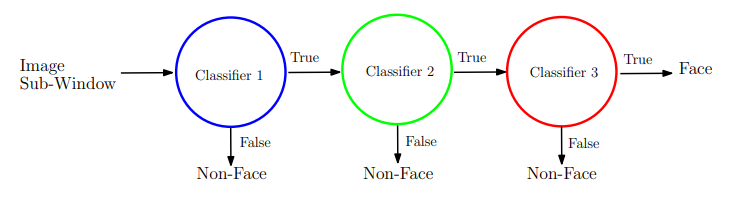

To be classified positively, a sliding window should pass all cascade stages. In case if any classifier rejects the window, it is immediately rejected and detector proceeds to the next window. As a result, that most of negative windows are rejected fast with first fast classifiers in the cascade. The detection rate (true positive rate, TP) of a cascade classifier is a multiplication of detection rates of all classifiers in a cascade:


$$TP = \prod_i TP_i.$$


The false positive rate (FP) is also a multiplication of false positives of cascade classifiers;


$$FP = \prod_i FP_i.$$


As a result, to build a classifier with 0.9 true positive rate and ${10}^{-6}$ false negative, each classifier in a cascade should meet the requirement of of 0.99 true positive and just 0.3 false positive. 

Each classifier of the cascade is trained using the AdaBoost training scheme with requirement to maximize the true positive detection rate with keeping false positive within a given range. The training set is modified between the boosting rounds to increase the complexity of each cascade step.

## **Task 1. Faces detection**

### 1.1 Viola-Jones approach with MATLAB

MATLAB provides `vision.CascadeObjectDetector `object. The cascade object detector uses the Viola-Jones algorithm to detect people’s faces, noses, eyes, mouth, or upper body using special parameters of the object. Of course, you can train the custom detector on your own objects using `Image Labeler:`

clc; clear all;

faceDetector = vision.CascadeObjectDetector;

After that you should apply your detector faceDetector to the image `I`. As a result, you will obtain the coordinates of the rectangular bounding boxes around the faces in a format `[x y width height]`, that specifies in pixels the upper-left corner and size of the bounding boxes.

I = imread('images/photo_faces.jpg');
bboxes = faceDetector(I);

In the last step you should place bounding boxes to the image. In MATLAB you can use the function `insertObjectAnnotation(I, shape, position, label[, optional parameters])`. Let’s place rectangular annotations to the faces and display it using `imshow(I)` function.

IFaces = insertObjectAnnotation(I, 'rectangle',bboxes,'Face');

figure;
imshow(IFaces);
title('Image with detected faces');

MATLAB provides several pretrained classifiers, e.g.` UpperBody, EyePairSmall, Mouth,` or `Nose`. The complete list you can find in [[vision.CascadeObjectDetector](https://www.mathworks.com/help/vision/ref/vision.cascadeobjectdetector-system-object.html)]. Specify the region of interest (ROI) in the detector detector(I,roi) you can find, for examples, eyes only in the regions of faces. To do that you should use the optional parameter UseROI with value true in the cascade object detector. For example, let’s detect eyes on the detected faces. 

eyesDetector = vision.CascadeObjectDetector('ClassificationModel','EyePairSmall','UseROI',true);

Unfortunately, MATLAB doesn’t allow to apply the whole array of bounding boxes from one detector to another one as ROI. So, let’s do it step-by-step.

counter = 1;
for i = 1:1:length(bboxes)
  temp = eyesDetector(I, bboxes(i,:));
  if ~isempty(temp)
    bboxes2(counter,:) = temp;
    counter = counter + 1;
  end
end

After that we can put labels of eyes to the previous image with faces’ annotations:

IEyes = insertObjectAnnotation(IFaces,'rectangle',bboxes2,'Eyes','Color','magenta');

figure;
imshow(IEyes);
title('Image with detected faces and eyes');

# ***Self-work***

Select **three** arbitrary images contains several faces. Try to use images with a different number of faces and different scales. Perform to search faces using Viola-Jones approach. Calculate the number of found faces on each image. 

% TODO Place your solution here
clc; clear all;

faceDetector = vision.CascadeObjectDetector;
Ilist = {'images/4.png', 'images/2.png', 'images/3.png'};
for i = 1:3
    I = imread(Ilist{i});
    bboxes = faceDetector(I);
    IFaces = insertObjectAnnotation(I, 'rectangle',bboxes,'Face');
    
    figure;
    imshow(IFaces);
    title(['Image with detected faces: ', num2str(length(bboxes))]);
end

## **Task 2. Body Parts Detection**

Now let us try to use custom pre-trained cascades for face detection:

- **haarcascade_frontalface_default.xml** is the default 24 x 24 window size pre-trained adaboost cascade for face detection. It has the higher detection rate but at the same time it has more false-positives.

- **haarcascade_frontalface_alt.xml** is an alternative 20 x 20 window size pre-trained adaboost cascade for face detection. It has a lower detection rate but also less false-positives.

- **haarcascade_frontalface_alt2.xml** and **haarcascade_frontalface_alt_tree.xml** are two other alternative 20 x 20 window size pre-trained adaboost cascade with tree-based decision tree.

- **haarcascade_profileface.xml** is a 20 x 20 window size pre-trained adaboost cascade for profile face detections.

Let us try creating a cascade classifier and loading a default built-in cascade for frontal face detection from a file **haarcascade_frontalface_default.xml **to find faces in a image.

clc; clear all;

% Read an image from a file in BGR
fn = 'images/photo_faces.jpg';
I2 = imread(fn);
if isempty(I2)
    error('Error reading file "%s"', fn);
end

% Convert to grayscale
I2gray = rgb2gray(I2);
% Equalize histogram for a better processing quality
I2gray = histeq(I2gray);

Now, we are going to upload face cascade file and set a threshold by adjusting scale factor (it is important, when we work with a high resolution image)

cascade_face = vision.CascadeObjectDetector('haarcascades/haarcascade_frontalface_default.xml');
cascade_face.ScaleFactor = 1.1;
cascade_face.MergeThreshold = 10;

% Detect faces
bboxes = step(cascade_face, I2gray);
fprintf('%d face(s) were detected\n', size(bboxes, 1));

% Highlight faces and search for eyes on each of them
I2out = I2;
I2faces = {};
for i = 1:size(bboxes, 1)
    x = bboxes(i, 1);
    y = bboxes(i, 2);
    w = bboxes(i, 3);
    h = bboxes(i, 4);
    
    % Draw a rectangle on an image to highlight the detected face with a yellow color
    I2out = insertShape(I2out, 'Rectangle', [x y w h], 'Color', [255 255 0], 'LineWidth', 3);
    
    % Extract face ROI from an image
    I2face = I2(y:y+h-1, x:x+w-1, :);
    
    % And add it to the cell array for displaying
    I2faces{end+1} = struct('title', sprintf('Face %d', length(I2faces)+1), 'image', I2face);
end

% Display it
figure;
subplot(1,2,1); imshow(I2); title('Source image');
subplot(1,2,2); imshow(I2out); title('Detected faces');

Now let us try to detect eyes on the found face. For this need, we will take a higher-resolution image of a face.

It's obvious that we don't need to scan the whole image for eyes as there would be a lot of false-positive results, so we will define a Region-Of-Interest (ROI) object as a face that was already found and then search for eyes by taking the ROI into an account. With Python, we can define the ROI by simply slicing an array as we already did when displaying the faces found. So, to detect eyes we should:

- Load a cascade for faces;

- Use the loaded face cascade to detect faces on the image;

- Load a cascade for eyes;

- Go through all detected faces and use the loaded eyes cascade to detect eyes on the face.

There are several cascades which may be used for body parts detections:

-  **haarcascade_eye.xml** for eyes detection;

-  **haarcascade_eye_tree_eyeglasses.xml** an alternative eyes detection cascade with a higher accuracy and allowing detection of eyes with eyeglasses;

-  **haarcascade_lefteye_2splits.xml** for detection of the left eye only;

-  **haarcascade_righteye_2splits.xml** for detection of the right eye only;

-  **haarcascade_smile.xml** for a smile (or mouth) detection.

And of course there are cascades for a whole body detection:

-  **haarcascade_fullbody.xml** for the full body;

-  **haarcascade_upperbody.xml** for the upper body;

-  **haarcascade_lowerbody.xml** for the lower body.

These cascades can be added to a first stage of detection if you need detect faces of pedestrians.

Firstly, let us find faces in the image in the same way, like it was done in the previous example.

clc; clear all;

% Read an image from a file in BGR
fn = 'images/face1.png';
I2 = imread(fn);
if isempty(I2)
    error('Error reading file "%s"', fn);
end

% Convert to grayscale
I2gray = rgb2gray(I2);
% Equalize histogram for a better processing quality
I2gray = histeq(I2gray);

% Load face cascade
cascade_face = vision.CascadeObjectDetector();
% Since our image has high resolution, we set a threshold by adjusting scale factor
cascade_face.ScaleFactor = 1.1;
cascade_face.MergeThreshold = 10;

% Detect faces
bboxes = step(cascade_face, I2gray);
fprintf('%d face(s) were detected\n', size(bboxes, 1));

% Highlight faces and search for eyes on each of them
I2out = I2;
I2faces = {};
for i = 1:size(bboxes, 1)
    x = bboxes(i, 1);
    y = bboxes(i, 2);
    w = bboxes(i, 3);
    h = bboxes(i, 4);
    
    % Draw a rectangle on an image to highlight the detected face with a yellow color
    I2out = insertShape(I2out, 'Rectangle', [x y w h], 'Color', [255 255 0], 'LineWidth', 3);
    
    % Extract face ROI from an image
    I2face = I2(y:y+h-1, x:x+w-1, :);
    
    % And add it to the cell array for displaying
    I2faces{end+1} = struct('title', sprintf('Face %d', length(I2faces)+1), 'image', I2face);
end

% Display it
figure;
subplot(1,2,1); imshow(I2); title('Source image');
subplot(1,2,2); imshow(I2out); title('Detected faces');

figure;
for i = 1:length(I2faces)
    subplot(1,length(I2faces),i); 
    imshow(I2faces{i}.image); 
    title(I2faces{i}.title);
end

Now we can load the eyes cascade and go through all the detected faces to find eyes and highlight them. We use `cascade_eyes = vision.CascadeObjectDetector()` to upload haar cascades for eyes. Also, use the following parameters to tune algorithm:

- MergeThreshold - reduce for more sensitivity;

- ScaleFactor - сhange for better accuracy or speed;

- MinSize and MaxSize - can be chosen as the assumed minimum and maximum sizes of the calculated boxes, respectively;

% Load cascade for eyes 
cascade_eyes = vision.CascadeObjectDetector('haarcascades/haarcascade_eye.xml', 'MergeThreshold', 5, 'ScaleFactor', 1.02, ...
    'MinSize', [20 20], 'MaxSize', [80 80]);

I2out_eyes = I2out;
I2faces_eyes = {};

% Go through all faces
for i = 1:size(bboxes, 1)
    % Take face and convert it to grayscale and normalize
    face = rgb2gray(I2faces{i}.image);
    face = histeq(face);
    
    % Then search for eyes
    eye_bboxes = step(cascade_eyes, face);
    fprintf('%d eyes were detected on face %d\n', size(eye_bboxes, 1), i);
    
    % Now go through all eyes
    I2face_out = I2faces{i}.image;
    for j = 1:size(eye_bboxes, 1)
        x = eye_bboxes(j, 1);
        y = eye_bboxes(j, 2);
        w = eye_bboxes(j, 3);
        h = eye_bboxes(j, 4);
        
        % Highlight them on the face
        I2face_out = insertShape(I2face_out, 'Rectangle', [x y w h], 'Color', [0 255 0], 'LineWidth', 1);
        % And on the source image
        % For this we have to shift eyes by face box position
        face_x = bboxes(i, 1);
        face_y = bboxes(i, 2);
        I2out_eyes = insertShape(I2out_eyes, 'Rectangle', [x+face_x y+face_y w h], 'Color', [0 255 0], 'LineWidth', 2);
    end
    
    I2faces_eyes{end+1} = struct('title', I2faces{i}.title, 'image', I2face_out);
end

% Display it
figure;
imshow(I2out_eyes); title('Detected faces and eyes');

figure;
for i = 1:length(I2faces_eyes)
    subplot(1,length(I2faces_eyes),i); 
    imshow(I2faces_eyes{i}.image); 
    title(I2faces_eyes{i}.title);
end

As we can see there is false detection of a eye. To solve this problem we must find new parameters fot the classificator (You can try to do this, see `cascade_eyes = vision.CascadeObjectDetector()`). 

But, the other way to reduce a value of faulce detection is to use **haarcascade_eye_tree_eyeglasses.xml. **As it was mentioned above it is an alternative eyes detection cascade with a higher accuracy and allowing detection of eyes with eyeglasses.

% Load cascade for eyes. Adjusted version
cascade_eyes = vision.CascadeObjectDetector('haarcascades/haarcascade_eye_tree_eyeglasses.xml', 'MergeThreshold', 5, ...    
'ScaleFactor', 1.02, 'MinSize', [20 20], 'MaxSize', [80 80]);

I2out_eyes = I2out;
I2faces_eyes = {};

% Go through all faces
for i = 1:size(bboxes, 1)
    % Take face and convert it to grayscale and normalize
    face = rgb2gray(I2faces{i}.image);
    face = histeq(face);
    
    % Then search for eyes
    eye_bboxes = step(cascade_eyes, face);
    fprintf('%d eyes were detected on face %d\n', size(eye_bboxes, 1), i);
    
    % Now go through all eyes
    I2face_out = I2faces{i}.image;
    for j = 1:size(eye_bboxes, 1)
        x = eye_bboxes(j, 1);
        y = eye_bboxes(j, 2);
        w = eye_bboxes(j, 3);
        h = eye_bboxes(j, 4);
        
        % Highlight them on the face
        I2face_out = insertShape(I2face_out, 'Rectangle', [x y w h], 'Color', [0 255 0], 'LineWidth', 1);
        % And on the source image
        % For this we have to shift eyes by face box position
        face_x = bboxes(i, 1);
        face_y = bboxes(i, 2);
        I2out_eyes = insertShape(I2out_eyes, 'Rectangle', [x+face_x y+face_y w h], 'Color', [0 255 0], 'LineWidth', 2);
    end
    
    I2faces_eyes{end+1} = struct('title', I2faces{i}.title, 'image', I2face_out);
end

% Display it
figure;
imshow(I2out_eyes); title('Detected faces and eyes');


figure;
for i = 1:length(I2faces_eyes)
    subplot(1,length(I2faces_eyes),i); 
    imshow(I2faces_eyes{i}.image); 
    title(I2faces_eyes{i}.title);
end

And so we done.

Here the example, how to find not only eyes. You can find eyes and a smile. 

clc; clear all;

imgPath = fullfile('images', 'face1.png'); 
img = imread(imgPath);

grayImg = rgb2gray(img);
grayImg = adapthisteq(grayImg); 

% Loading cascade classifiers all together
faceCascadePath = fullfile('haarcascades', 'haarcascade_frontalface_default.xml');
eyeCascadePath = fullfile('haarcascades', 'haarcascade_eye_tree_eyeglasses.xml'); 
smileCascadePath = fullfile('haarcascades', 'haarcascade_smile.xml');

% Initialising detectors
faceDetector = vision.CascadeObjectDetector(faceCascadePath, 'MergeThreshold', 10);
eyeDetector = vision.CascadeObjectDetector(eyeCascadePath, 'MergeThreshold', 5);
smileDetector = vision.CascadeObjectDetector(smileCascadePath, 'MergeThreshold', 5); % Улыбки требуют меньшего порога


bboxFaces = faceDetector.step(grayImg);
fprintf('%d face(s) were detected\n', size(bboxFaces, 1));

% Preparing the image for markup
resultImg = img;

% Treating each face
for i = 1:size(bboxFaces, 1)
    x = bboxFaces(i, 1);
    y = bboxFaces(i, 2);
    w = bboxFaces(i, 3);
    h = bboxFaces(i, 4);
    
    resultImg = insertShape(resultImg, 'Rectangle', bboxFaces(i,:), ...
        'Color', 'yellow', 'LineWidth', 3);
    
    % Eye search (upper 50% of the face)
    eyeROI = [x, y + h*0.2, w, h*0.4]; % Area: 10% to 50% of the face height
    grayEyeROI = grayImg(eyeROI(2):eyeROI(2)+eyeROI(4)-1, eyeROI(1):eyeROI(1)+eyeROI(3)-1);
    
    bboxEyes = eyeDetector.step(grayEyeROI);
    
    % Eye size filtering for increased accuracy
    for j = 1:size(bboxEyes, 1)
        eyeW = bboxEyes(j, 3);
        if eyeW > w*0.15 && eyeW < w*0.3 % discard objects that are too big/small
            bboxEyes(j,1) = bboxEyes(j,1) + eyeROI(1);
            bboxEyes(j,2) = bboxEyes(j,2) + eyeROI(2);
            resultImg = insertShape(resultImg, 'Rectangle', bboxEyes(j,:), ...
                'Color', 'green', 'LineWidth', 3);
        end
    end
    
    % Finding smiles (lower 30% of the face)
    smileROI = [x, y + h*0.75, w, h*0.3]; % Area: 60% to 90% of the face height
    graySmileROI = grayImg(smileROI(2):smileROI(2)+smileROI(4)-1, smileROI(1):smileROI(1)+smileROI(3)-1);
    
    bboxSmiles = smileDetector.step(graySmileROI);
    
    % Eye size filtering for increased accuracy
    for j = 1:size(bboxSmiles, 1)
        smileW = bboxSmiles(j, 3);
        if smileW > w*0.2 && smileW < w*0.6 
            bboxSmiles(j,1) = bboxSmiles(j,1) + smileROI(1);
            bboxSmiles(j,2) = bboxSmiles(j,2) + smileROI(2);
            resultImg = insertShape(resultImg, 'Rectangle', bboxSmiles(j,:), ...
                'Color', 'red', 'LineWidth', 3);
        end
    end
end
figure;
imshow(resultImg);
title('Face(s), eye(s) и smile(s)');

# ***Self-work***

Select **three** arbitrary images contains several faces. Try to use images with a different number of faces and different scales. Perform to search at least two parts of bodies in the one image (e.g. eyes, mouths, noses). To increase the accuracy use ROI (upper part of bodies or faces). Calculate the found elements in each category.  

% TODO Place your solution here
Ilist = {'images/4.png', 'images/2.png', 'images/3.png'};


i = 1;
img = imread(Ilist{i});
grayImg = rgb2gray(img);
grayImg = adapthisteq(grayImg); 

% Loading cascade classifiers all together
faceCascadePath = fullfile('haarcascades', 'haarcascade_frontalface_default.xml');
eyeCascadePath = fullfile('haarcascades', 'haarcascade_eye.xml'); 
smileCascadePath = fullfile('haarcascades', 'haarcascade_smile.xml');

% Initialising detectors
faceDetector = vision.CascadeObjectDetector(faceCascadePath, 'MergeThreshold', 10);
eyeDetector = vision.CascadeObjectDetector(eyeCascadePath, 'MergeThreshold', 5);
smileDetector = vision.CascadeObjectDetector(smileCascadePath, 'MergeThreshold', 5); % Улыбки требуют меньшего порога


bboxFaces = faceDetector.step(grayImg);
fprintf('%d face(s) were detected\n', size(bboxFaces, 1));

4 face(s) were detected



% Preparing the image for markup
resultImg = img;
eyesc = 0;
simlesc = 0;

% Treating each face
for i = 1:size(bboxFaces, 1)
    x = bboxFaces(i, 1);
    y = bboxFaces(i, 2);
    w = bboxFaces(i, 3);
    h = bboxFaces(i, 4);
    
    resultImg = insertShape(resultImg, 'Rectangle', bboxFaces(i,:), ...
        'Color', 'yellow', 'LineWidth', 3);
    
    % Eye search (upper 50% of the face)
    eyeROI = [x, y + h*0.1, w, h*0.5]; % Area: 10% to 50% of the face height
    grayEyeROI = grayImg(eyeROI(2):eyeROI(2)+eyeROI(4)-1, eyeROI(1):eyeROI(1)+eyeROI(3)-1);
    
    bboxEyes = eyeDetector.step(grayEyeROI);
    % Eye size filtering for increased accuracy
    for j = 1:size(bboxEyes, 1)
        eyeW = bboxEyes(j, 3);
        if eyeW > w*0.1 && eyeW < w*0.5 % discard objects that are too big/small
            bboxEyes(j,1) = bboxEyes(j,1) + eyeROI(1);
            bboxEyes(j,2) = bboxEyes(j,2) + eyeROI(2);
            resultImg = insertShape(resultImg, 'Rectangle', bboxEyes(j,:), ...
                'Color', 'green', 'LineWidth', 3);
            eyesc = eyesc + 1;
        end
    end
    
    % Finding smiles (lower 30% of the face)
    smileROI = [x, y + h*0.5, w, h*0.45]; % Area: 50% to 95% of the face height
    graySmileROI = grayImg(smileROI(2):smileROI(2)+smileROI(4)-1, smileROI(1):smileROI(1)+smileROI(3)-1);
    
    bboxSmiles = smileDetector.step(graySmileROI);
    
    % Eye size filtering for increased accuracy
    for j = 1:size(bboxSmiles, 1)
        smileW = bboxSmiles(j, 3);
        if smileW > w*0.2 && smileW < w*0.6 
            bboxSmiles(j,1) = bboxSmiles(j,1) + smileROI(1);
            bboxSmiles(j,2) = bboxSmiles(j,2) + smileROI(2);
            resultImg = insertShape(resultImg, 'Rectangle', bboxSmiles(j,:), ...
                'Color', 'red', 'LineWidth', 3);
            simlesc = simlesc + 1;
        end
    end
end


fprintf('%d face(s) were detected\n', size(bboxFaces, 1));

4 face(s) were detected


fprintf('%d Eyes(s) were detected\n', eyesc);

5 Eyes(s) were detected



fprintf('%d Smile(s) were detected\n', simlesc);

4 Smile(s) were detected


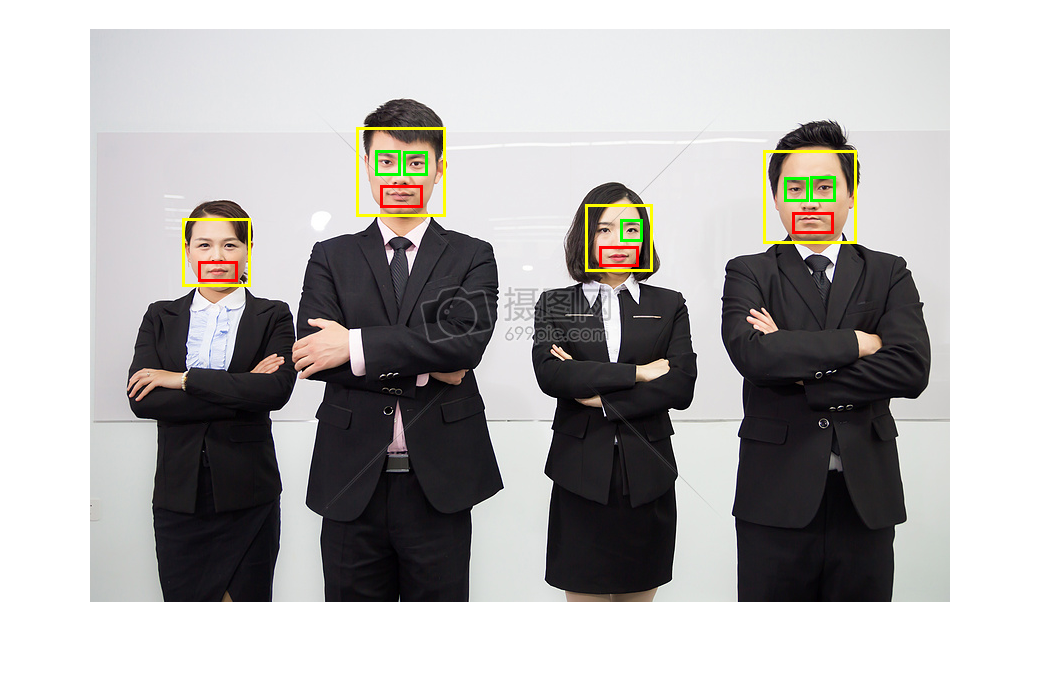

figure;
imshow(resultImg);


Ilist = {'images/4.png', 'images/2.png', 'images/3.png'};
i = 2;
img = imread(Ilist{i});
grayImg = rgb2gray(img);
grayImg = adapthisteq(grayImg); 

% Loading cascade classifiers all together
faceCascadePath = fullfile('haarcascades', 'haarcascade_frontalface_default.xml');
eyeCascadePath = fullfile('haarcascades', 'haarcascade_eye.xml'); 
smileCascadePath = fullfile('haarcascades', 'haarcascade_smile.xml');

% Initialising detectors
faceDetector = vision.CascadeObjectDetector(faceCascadePath, 'MergeThreshold', 10);
eyeDetector = vision.CascadeObjectDetector(eyeCascadePath, 'MergeThreshold', 5);
smileDetector = vision.CascadeObjectDetector(smileCascadePath, 'MergeThreshold', 5); % Улыбки требуют меньшего порога


bboxFaces = faceDetector.step(grayImg);
fprintf('%d face(s) were detected\n', size(bboxFaces, 1));

2 face(s) were detected



% Preparing the image for markup
resultImg = img;
eyesc = 0;
simlesc = 0;

% Treating each face
for i = 1:size(bboxFaces, 1)
    x = bboxFaces(i, 1);
    y = bboxFaces(i, 2);
    w = bboxFaces(i, 3);
    h = bboxFaces(i, 4);
    
    resultImg = insertShape(resultImg, 'Rectangle', bboxFaces(i,:), ...
        'Color', 'yellow', 'LineWidth', 3);
    
    % Eye search (upper 50% of the face)
    eyeROI = [x, y + h*0.3, w, h*0.4]; % Area: 10% to 50% of the face height
    grayEyeROI = grayImg(eyeROI(2):eyeROI(2)+eyeROI(4)-1, eyeROI(1):eyeROI(1)+eyeROI(3)-1);
    
    bboxEyes = eyeDetector.step(grayEyeROI);
    
    % Eye size filtering for increased accuracy
    for j = 1:size(bboxEyes, 1)
        eyeW = bboxEyes(j, 3);
        if eyeW > w*0.1 && eyeW < w*0.3 % discard objects that are too big/small
            bboxEyes(j,1) = bboxEyes(j,1) + eyeROI(1);
            bboxEyes(j,2) = bboxEyes(j,2) + eyeROI(2);
            resultImg = insertShape(resultImg, 'Rectangle', bboxEyes(j,:), ...
                'Color', 'green', 'LineWidth', 3);
            eyesc = eyesc + 1;
        end
    end
    
    % Finding smiles (lower 30% of the face)
    smileROI = [x, y + h*0.5, w, h*0.45]; % Area: 50% to 95% of the face height
    graySmileROI = grayImg(smileROI(2):smileROI(2)+smileROI(4)-1, smileROI(1):smileROI(1)+smileROI(3)-1);
    
    bboxSmiles = smileDetector.step(graySmileROI);
    
    % Eye size filtering for increased accuracy
    for j = 1:size(bboxSmiles, 1)
        smileW = bboxSmiles(j, 3);
        if smileW > w*0.1 && smileW < w*0.7 
            bboxSmiles(j,1) = bboxSmiles(j,1) + smileROI(1);
            bboxSmiles(j,2) = bboxSmiles(j,2) + smileROI(2);
            resultImg = insertShape(resultImg, 'Rectangle', bboxSmiles(j,:), ...
                'Color', 'red', 'LineWidth', 3);
            simlesc = simlesc + 1;
        end
    end
end

fprintf('%d face(s) were detected\n', size(bboxFaces, 1));

2 face(s) were detected


fprintf('%d Eyes(s) were detected\n', eyesc);

4 Eyes(s) were detected



fprintf('%d Smile(s) were detected\n', simlesc);

2 Smile(s) were detected


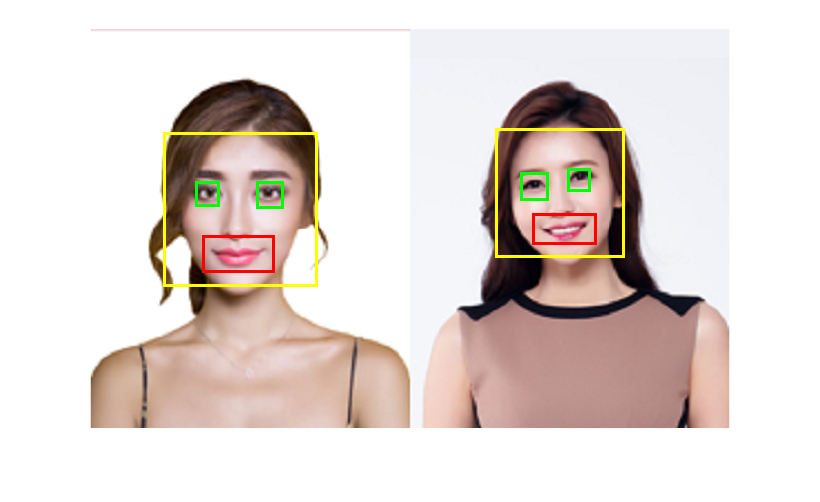

figure;
imshow(resultImg);


Ilist = {'images/4.png', 'images/2.png', 'images/3.png'};
i = 3;
img = imread(Ilist{i});
grayImg = rgb2gray(img);
grayImg = adapthisteq(grayImg); 

% Loading cascade classifiers all together
faceCascadePath = fullfile('haarcascades', 'haarcascade_frontalface_default.xml');
eyeCascadePath = fullfile('haarcascades', 'haarcascade_eye.xml'); 
smileCascadePath = fullfile('haarcascades', 'haarcascade_smile.xml');

% Initialising detectors
faceDetector = vision.CascadeObjectDetector(faceCascadePath, 'MergeThreshold', 10);
eyeDetector = vision.CascadeObjectDetector(eyeCascadePath, 'MergeThreshold', 5);
smileDetector = vision.CascadeObjectDetector(smileCascadePath, 'MergeThreshold', 5); % Улыбки требуют меньшего порога


bboxFaces = faceDetector.step(grayImg);
fprintf('%d face(s) were detected\n', size(bboxFaces, 1));

3 face(s) were detected



% Preparing the image for markup
resultImg = img;

eyesc = 0;
simlesc = 0;
% Treating each face
for i = 1:size(bboxFaces, 1)
    x = bboxFaces(i, 1);
    y = bboxFaces(i, 2);
    w = bboxFaces(i, 3);
    h = bboxFaces(i, 4);
    
    resultImg = insertShape(resultImg, 'Rectangle', bboxFaces(i,:), ...
        'Color', 'yellow', 'LineWidth', 3);
    
    % Eye search (upper 50% of the face)
    eyeROI = [x, y + h*0.1, w, h*0.42]; % Area: 10% to 50% of the face height
    grayEyeROI = grayImg(eyeROI(2):eyeROI(2)+eyeROI(4)-1, eyeROI(1):eyeROI(1)+eyeROI(3)-1);
    
    bboxEyes = eyeDetector.step(grayEyeROI);
    
    % Eye size filtering for increased accuracy
    for j = 1:size(bboxEyes, 1)
        eyeW = bboxEyes(j, 3);
        if eyeW > w*0.1 && eyeW < w*0.3 % discard objects that are too big/small
            bboxEyes(j,1) = bboxEyes(j,1) + eyeROI(1);
            bboxEyes(j,2) = bboxEyes(j,2) + eyeROI(2);
            resultImg = insertShape(resultImg, 'Rectangle', bboxEyes(j,:), ...
                'Color', 'green', 'LineWidth', 3);
            eyesc = eyesc + 1;
        end
    end
    
    % Finding smiles (lower 30% of the face)
    smileROI = [x, y + h*0.5, w, h*0.45]; % Area: 50% to 95% of the face height
    graySmileROI = grayImg(smileROI(2):smileROI(2)+smileROI(4)-1, smileROI(1):smileROI(1)+smileROI(3)-1);
    
    bboxSmiles = smileDetector.step(graySmileROI);
    
    % Eye size filtering for increased accuracy
    for j = 1:size(bboxSmiles, 1)
        smileW = bboxSmiles(j, 3);
        if smileW > w*0.3 && smileW < w*0.6 
            bboxSmiles(j,1) = bboxSmiles(j,1) + smileROI(1);
            bboxSmiles(j,2) = bboxSmiles(j,2) + smileROI(2);
            resultImg = insertShape(resultImg, 'Rectangle', bboxSmiles(j,:), ...
                'Color', 'red', 'LineWidth', 3);
            simlesc = simlesc + 1;
        end
    end
end

fprintf('%d face(s) were detected\n', size(bboxFaces, 1));

3 face(s) were detected


fprintf('%d Eyes(s) were detected\n', eyesc);

6 Eyes(s) were detected



fprintf('%d Smile(s) were detected\n', simlesc);

3 Smile(s) were detected


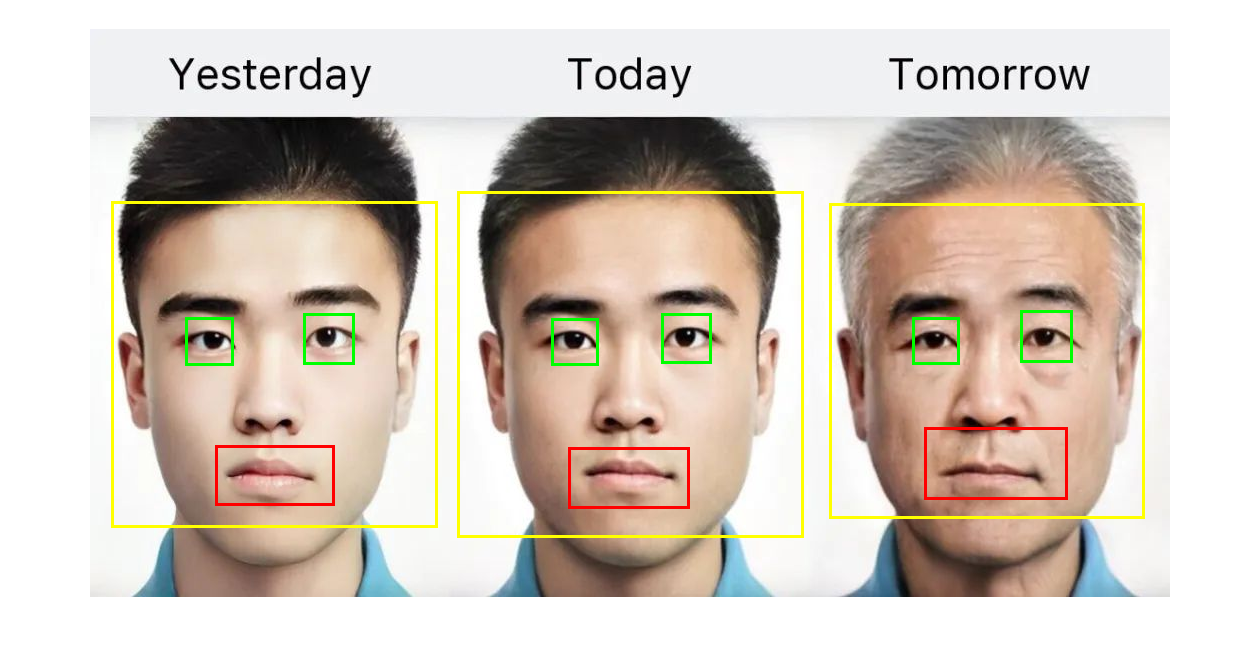

figure;
imshow(resultImg);

## **Task 3. Optional. Face Detection in Video Footage**

Here is the code you can take to play a video file in a matlab environment.

% clc; clear all;
% 
% videoPath = 'video/video_students.mp4'; 
% 
% %% Initialisation of objects
% videoReader = VideoReader(videoPath);
% 
% % Creating a video player for display
% videoPlayer = vision.VideoPlayer('Name', 'Video Playback');
% 
% %% Video playback
% while hasFrame(videoReader)
%     % Frame reading
%     frame = readFrame(videoReader);
%     
%     % Displaying the original frame
%     step(videoPlayer, frame);
%     
%     % Forced interruption on closing the player
%     if ~isOpen(videoPlayer)
%         break;
%     end
% end
% 
% %% Completion of work
% release(videoPlayer);

**Implement the face detection in videostream using pre-recorded video with faces.**

To implement face detection, you should to add the following algorithm steps:

1. Initialising the face detector

- Loading the cascade classifier from an XML file (e.g. haarcascade_frontalface_default.xml).

- Setting up the detector parameters: MergeThreshold - sensitivity to grouping of detected areas (the higher, the stricter), MinSize/MaxSize - minimum and maximum face size in pixels.

2. Processing of each video frame

- Reading a frame from a video file.

- Converting the frame to grayscale (Haar detectors work with black and white images).

- Histogram normalisation (e.g. histeq or adapthisteq) to improve contrast.

3. Face detection

- Applying the detector to the current frame.

- Obtaining the coordinates of rectangles (bbox) around detected faces.

4. Visualisation of results

- Drawing rectangles around the faces on the original frame.

- Adding captions (e.g. ‘Face’) to improve visualisation.

% TODO Place your solution here





# ***Self-work***

**Answer questions and conclude your work results.**

## **Questions**

Please answer the following questions:

 -   What is the special image representation used in the Viola-Jones approach? 

The integral image representation is used, which allows for fast computation of Haar-like features by summing pixel values in rectangular regions efficiently.

 - What is the main advantage of Haar-like features for classifier training?

Haar-like features are computationally efficient due to the integral image, and they capture simple edge, line, and texture patterns, making them effective for object detection.

 - Could you use Viola-Jones approach for detecting arbitrary objects and why

Yes, but with limitations. It works best for rigid objects (faces, cars) with distinct patterns. For complex or deformable objects, deep learning (e.g., CNNs) is more effective.

 -  How to use feature points for stitching a panoramic image? 

Feature points (e.g., SIFT, SURF) detect keypoints in overlapping images. Matching these points allows alignment via homography transformation, blending images into a panorama.

## **Conclusion**

What have you learned with this task? Don't forget to conclude it.

This task demonstrated the Viola-Jones algorithm for face and body part detection using Haar cascades. Key takeaways:

Importance of ROI selection and parameter tuning (e.g., `MergeThreshold`, `ScaleFactor`) for accuracy.

Challenges with false positives/negatives and the need for cascades like `haarcascade_eye_tree_eyeglasses.xml`.

The method is fast but less robust compared to modern deep learning approaches for complex scenarios.

Practical experience in MATLAB for image processing and detector implementation.